clc
clear

load a.mat
load vmax.mat
load maxx.mat
load M.mat
load dmdt.mat


z=1;%第一组数据（两行一组）

m=M./2;
k=dmdt(2*z-1,1);
i=dmdt(2*z,1);%k1和k2
b1=zeros(6);
b2=b1;
dmdtk=dmdt(2*z-1,2:5);
dmdti=dmdt(2*z,2:5);

x=200:200:800;%降水量

new_x=100:200:900;
p=pchip(x,dmdtk,new_x);%插值
y=zeros(1,9);
for j=1:9
   if mod(j,2)==0
       y(j)=dmdtk(j/2);
   else
       y(j)=p((j+1)/2);
   end
end

x=100:100:900;
%x=200:200:800;

fun2=@(k,x) a(5,k).*vmax(k)./(1+a(1,k).*exp(a(2,k).*(x-a(3,k))))+a(5,k).*vmax(k)./(1+a(1,k).*exp(-a(2,k).*(x-a(3,k)-a(4,k)))) - 1.5.*vmax(k);



b0=[-20,1,-10];
b0=rand(1,3);
for o=1:10
    fun=@(b,x) fun2(k,x)*m(k)^2*(1- ( m(k)/( M(k)+b(1)*m(i)^2+b(2)*m(i) ) ) -b(3));
    
    [b,resnorm]=lsqcurvefit(fun,b0,x,y,[-10000,0,-100],[0,10000,100]);
    %[b,resnorm]=lsqcurvefit(fun,b0,x,dmdtk,[-10000,-10000],[0,10000]);
    b0=b;
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<

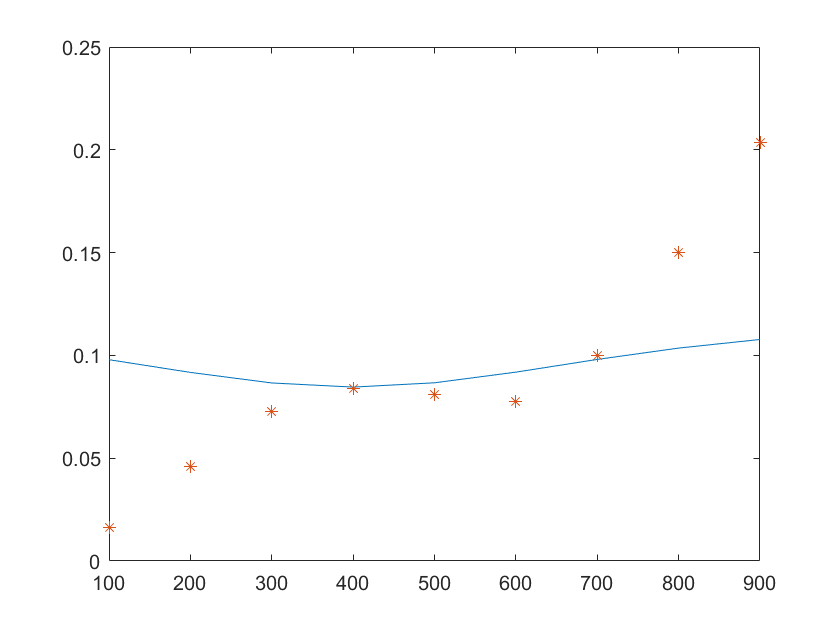



%dmdtk=v(k)*m(k)*(1- ( m(k)/( M(k)+b1(k,i)*m(i)^2+b2(k,i)*m(i) ) ) )

% v(i)=a(5,i)*vmax(i)/(1+a(1,i)*exp(a(2,i)*(x-a(3,i))))+a(5,i)*vmax(i)/(1+a(1,i)*exp(-a(2,i)*(x-a(3,i)-a(4,i)))) - 1.5*vmax(i);
% v(i)=v(i)*m(i);%百分比的原因
%dmdti=dmdt(2*z,2:5)
%dmdti=v(i)*m(i)*(1- ( m(i)/( M(i)+b1(i,k)*m(k)^2+b2(i,k)*m(k) ) ) )
b1(k,i)=b(1);
b2(k,i)=b(2);
plot(x,fun(b,x),x,y,'*');

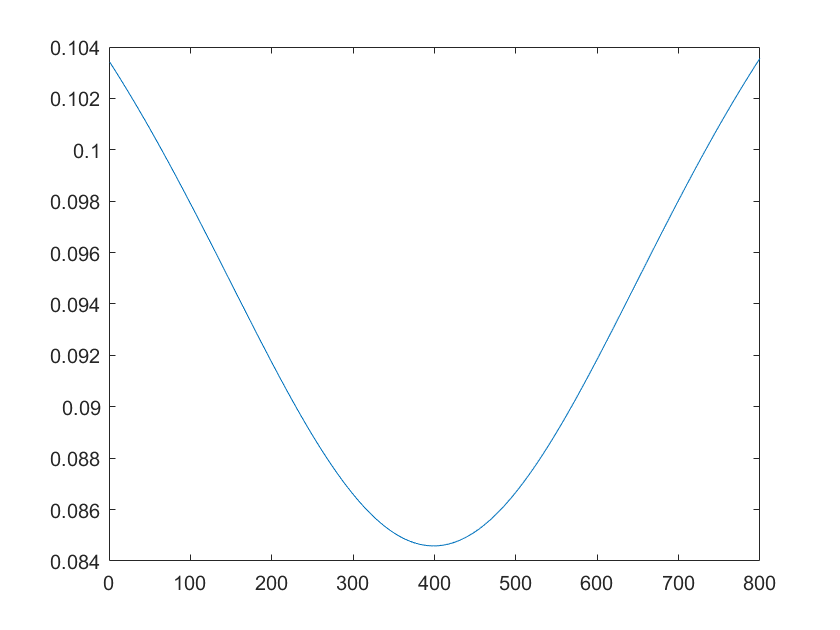


%(a(5,k)*vmax(k)/(1+a(1,k)*exp(a(2,k)*(x-a(3,k))))+a(5,k)*vmax(k)/(1+a(1,k)*exp(-a(2,k)*(x-a(3,k)-a(4,k)))) - 1.5*vmax(k))*m(k)*(1- ( m(k)/( M(k)+b1(k,i)*m(i)^2+b2(k,i)*m(i) ) ) );

x=1:1:800;
plot(x,fun(b,x))